dataPath = 'DATASET/';
%
% 0. Load data of accelerometer and rotation matrix
%
dataUsage = 'Linear Acceleration Sensor';
fData = dir(fullfile(dataPath,strcat('*',dataUsage,'*.txt')));
RawData = cell(length(fData),12);
for i=1:length(fData)
    curAccelerationData = load(strcat(dataPath,fData(i).name));
    curRotationData = load(strcat(dataPath,strrep(fData(i).name,dataUsage,'Rotation Matrix')));
    
    
    idxID = strfind(fData(i).name,'ID');
    curID = str2double(fData(i).name(idxID+2:idxID+3));
    curGender = fData(i).name(idxID+5);
    idxSessionID = strfind(fData(i).name,'_');
    curSessionID = str2double([fData(i).name(idxID+2:idxID+3) fData(i).name(idxSessionID(2)+1:idxSessionID(3)-1)]);curOrder = str2double(fData(i).name(idxSessionID(end)+1:strfind(fData(i).name,'.txt')-1));
    curOrder = str2double(fData(i).name(idxSessionID(end)+1:strfind(fData(i).name,'.txt')-1));
    
    RawData{i,1} = curAccelerationData;
    
    RawData{i,2} = curRotationData;
    RawData{i,3} = curID;
    RawData{i,4} = curGender;
    RawData{i,5} = curSessionID;
    RawData{i,6} = curOrder;
end
% PREPROCESSING:
%      
% 
%   ACCELEROMETER DATA CALIBRATION
%   Input: [Raw_Acceleration_Data Rotation_Matrix]
%   Output: [Calibrated_Data] 

for i = 1: length(RawData)
   RawData{i,2} =  calibrateAccelerometerData(RawData{i,1},RawData{i,2});
end
%
%   LINEAR INTERPOLATION
%   Input: [accelerometer data]
%   Ouput: [Interpolated_accelerometer_data]

for i =1: length(RawData)
   RawData{i,2} = linearInterpolation(RawData{i,2});  
end
%
%   NOISE ELIMINATION
%   Input:   [accelerometer_data]
%   Output:  [noise_reduced_accelerometer_data]
%
for i = 1: length(RawData)
   RawData{i,2} = eliminateNoise('db6',2,RawData{i,2}); 
end

%
%   SEGMENTATION
%
%   GAIT CYCLE DETECTION
%        
%   Input:  [accelerometer_data ]
%   Output: [peak_position]

for i = 1: length(RawData)
    peak_pos = detectGaitCycle(RawData{i,2});
    
    RawData{i,7} = peak_pos;
end

%  GAIT CYCLE BASED SEGMENTATION
%       
%  Input:  [accelerometer_data peak_position]
%  Output: [1-gait cycle based segments]

for i = 1:length(RawData)
   segments = segment2GaitCycle(RawData{i,2},RawData{i,7});
   RawData{i,8} = segments;
end

%  GAIT PATTERN EXTRACTION
%  
%  Input: [1-gait cycle based segments n p]
%  Output:[gait_patterns]
n = 4; p = 0.5;
for i=1:length(RawData)
    gait_patterns = extractGaitPattern(RawData{i,8},n,p);
    RawData{i,9} = gait_patterns;
end

%
%   FEATURE EXTRACTION
%   Input:  [Gait Pattern]
%   Output: [feature vectors]

for i =1:length(RawData)
   time_features = extractFeature_timedomain(RawData{i,9});
   frequency_features = extractFeature_frequencydomain(RawData{i,9});
   RawData{i,10} = time_features;
   RawData{i,11} = frequency_features;
end
%
%   FEATURE VECTOR CONCATENATION
%       
selectedAxis = [3 4 5]; % use features of Z, MXY, MXYZ axes
for i =1:length(RawData)
    curTimeFeature = RawData{i,10};
    curFrequencyFeature = RawData{i,11};
    concatFeature = {};
    for ii = 1:length(curTimeFeature)
    lastTimeFeature = curTimeFeature{ii,1}(end);
    concatTimeFeature = [lastTimeFeature ];
    for iii = 1:length(selectedAxis)
        concatTimeFeature = [concatTimeFeature curTimeFeature{ii,1}(1:end-1,selectedAxis(iii))'];
    end
    concatFrequencyFeature = [];
    for iii = 1:length(selectedAxis)
        concatFrequencyFeature = [concatFrequencyFeature curFrequencyFeature{ii,1}(:,selectedAxis(iii))'];
    end
    concatFeature{ii,1} = [ concatFrequencyFeature concatTimeFeature];    
    end
    RawData{i,12} = concatFeature;
end
%
%   DATA DIVISION
%   
%   
dataTrain = RawData(mod(cell2mat(RawData(:,6)),2)==0,:);
dataTest = RawData(mod(cell2mat(RawData(:,6)),2)==1,:);
%
%   FEATURE MATRIX AND LABEL VECTOR GENERATION
%   
%
%   TRAINING part
featureMatTrain = [];
labelVecTrain = [];
sessionVecTrain = [];
for i = 1: length(dataTrain)
    featureMatTrain = [featureMatTrain;cell2mat(dataTrain{i,12})];
    tempVec = zeros(length(dataTrain{i,12}),1);
    tempVec(:) = dataTrain{i,3};
    labelVecTrain = [labelVecTrain; tempVec];
    
    tempVec = zeros(length(dataTrain{i,12}),1);
    tempVec(:) = dataTrain{i,5};
    sessionVecTrain = [sessionVecTrain;tempVec];
end

%   TESTING part
featureMatTest = [];
labelVecTest = [];
sessionVecTest = [];
for i = 1: length(dataTest)
    featureMatTest = [featureMatTest;cell2mat(dataTest{i,12})];
    tempVec = zeros(length(dataTest{i,12}),1);
    tempVec(:) = dataTest{i,3};
    labelVecTest = [labelVecTest; tempVec];
    
    tempVec = zeros(length(dataTest{i,12}),1);
    tempVec(:) = dataTest{i,5};
    sessionVecTest = [sessionVecTest;tempVec];
end

## RECOGNITION

% TRAINING
% Apply PCA to training data
[featureMatTrain,eigenVec,meanVec] = eigenGait(featureMatTrain);

% Normalize the training data to -1...1 scale
max_val = max(featureMatTrain);
min_val = min(featureMatTrain);
max_valTrain = repmat(max_val,size(featureMatTrain,1),1);
min_valTrain = repmat(min_val,size(featureMatTrain,1),1);
featureMatTrain = ((featureMatTrain-min_valTrain)./(max_valTrain-min_valTrain) - 0.5 ) *2; 
svmModel = svmtrain([labelVecTrain],[featureMatTrain],'-t 0 -b 1');

*
optimization finished, #iter = 128
nu = 0.039359
obj = -4.024336, rho = -0.493691
nSV = 22, nBSV = 3
Total nSV = 22
*
optimization finished, #iter = 114
nu = 0.042159
obj = -4.170037, rho = -0.386820
nSV = 19, nBSV = 3
Total nSV = 19
*
optimization finished, #iter = 77
nu = 0.044108
obj = -4.305975, rho = -0.368943
nSV = 19, nBSV = 3
Total nSV = 19
*
optimization finished, #iter = 193
nu = 0.040136
obj = -4.069075, rho = -0.305296
nSV = 22, nBSV = 2
Total nSV = 22
*.*
optimization finished, #iter = 207
nu = 0.042987
obj = -4.169911, rho = -0.183868
nSV = 23, nBSV = 1
Total nSV = 23
*
optimization finished, #iter = 144
nu = 0.037200
obj = -4.619640, rho = -0.253868
nSV = 20, nBSV = 2
*
optimization finished, #iter = 107
nu = 0.015821
obj = -1.787892, rho = -0.652675
nSV = 19, nBSV = 0
Total nSV = 19
*
optimization finished, #iter = 82
nu = 0.016055
obj = -1.814336, rho = -0.658683
nSV = 16, nBSV = 0
Total nSV = 16
*
optimization finished, #iter = 94
nu = 0.015636
obj = -1.758927, rho 


% 
% TESTING
% Apply PCA to testing data using eigen vector and mean value obtained in training phase
meanMat = repmat(meanVec,size(featureMatTest,1),1);
featureMatTest = (featureMatTest - meanMat)*eigenVec;

% normalize feature matrix based on max min values extracted from the training phase
max_valTest = repmat(max_val,size(featureMatTest,1),1);
min_valTest = repmat(min_val,size(featureMatTest,1),1);
featureMatTest = ((featureMatTest-min_valTest)./(max_valTest-min_valTest) - 0.5 ) *2;

## RECOGNITION using SVM

## Consider EACH SEGMENT as a testing sample....

[predicted_label, accuracy, decision_val] =svmpredict(labelVecTest, featureMatTest, svmModel, '-b 1');

Accuracy = 95.0121% (4705/4952) (classification)


acc = accuracy(1)

acc = 95.0121

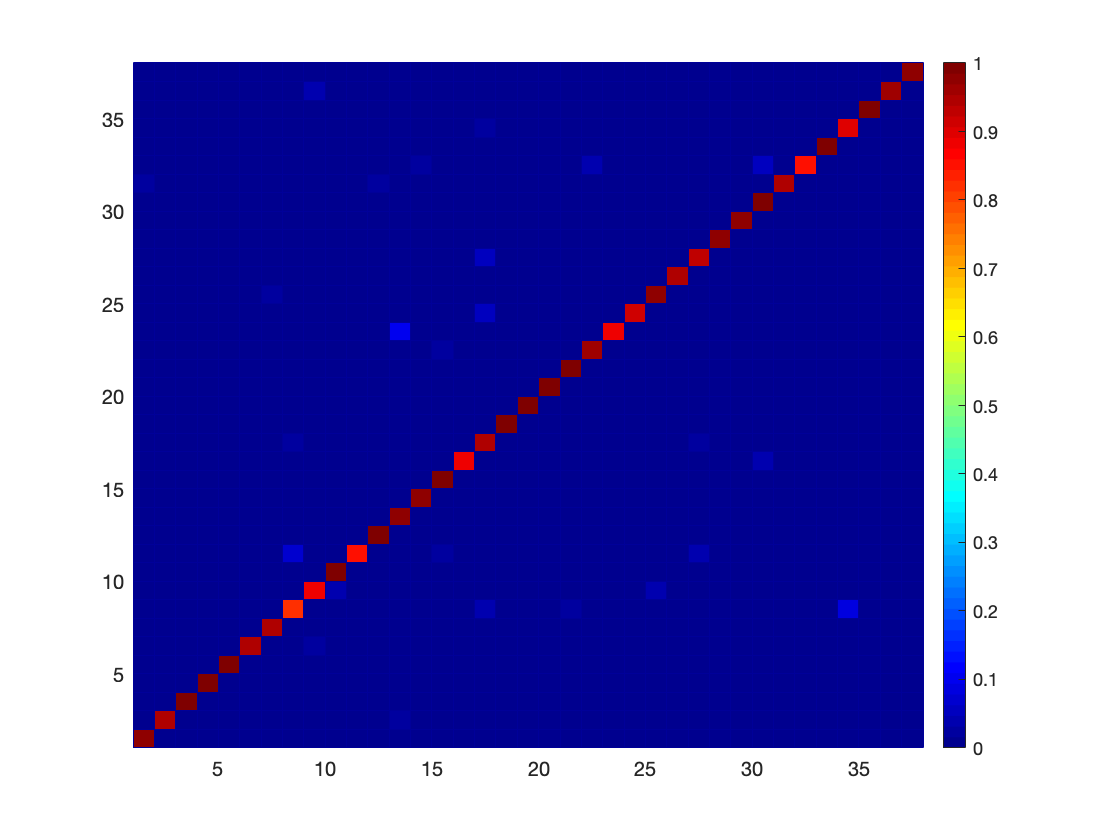

%temp = featureMatTest(1,:)
%[predicted_label_one, accuracy_one, decision_val_one] =svmpredict(featureMatTest(1,:), svmModel, '-b 1');

% mat2svm(featureMatTest,'test.txt')
% plot confusion Matrix
plotConfusionMatrix(1, labelVecTest,predicted_label)

% mat2svm(svmModel,'model.txt')

## Consider EACH SESSION as a testing sample....

Use majority voting 

recognition = [labelVecTest predicted_label];
uniSessionTest = unique(sessionVecTest);
trueLabel = zeros(length(uniSessionTest),1);
predictLabel = zeros(length(uniSessionTest),1);
for i = 1 : length(uniSessionTest)
    curRecognition = recognition(sessionVecTest==uniSessionTest(i),:);
    trueLabel(i) = curRecognition(1,1);
    predictLabelVec = unique(curRecognition(:,2)); % to determine how many labels that are predicted
    predictLabelCount = zeros(length(predictLabelVec),1); % to count the predicted labels
    for ii=1: length(predictLabelVec)
        predictLabelCount(ii,:)=sum(curRecognition(:,2)==predictLabelVec(ii));
    end
    predictLabel(i)=min(predictLabelVec(predictLabelCount==max(predictLabelCount)));
end
noCorrect = 0;
for i = 1 :length(predictLabel)
    if(predictLabel(i)==trueLabel(i))
        noCorrect = noCorrect +1;
    end
end
acc = noCorrect / length(predictLabel)

acc = 0.9914

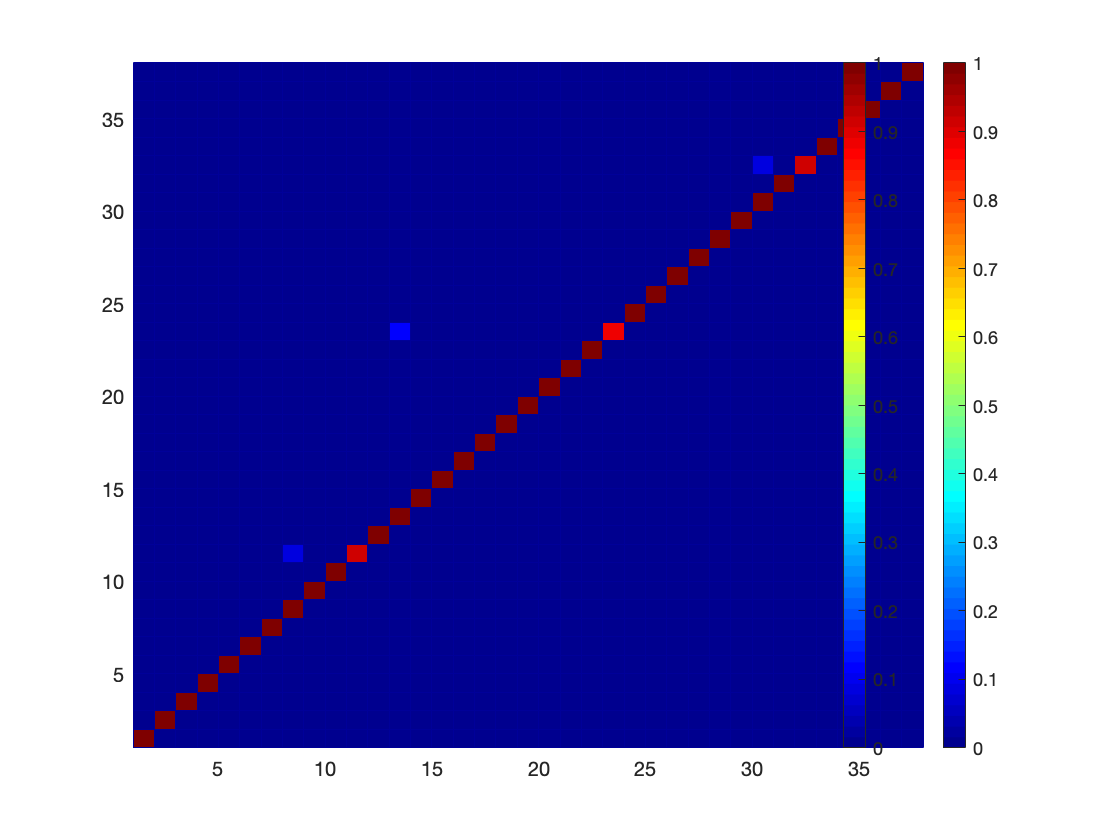

% plot confusion mat
plotConfusionMatrix(2, trueLabel,predictLabel);

## RECOGNITION using k Nearest Neighbor

`Calculate the matrix distance between two data of training & testing`

matDistance = pdist2(featureMatTest,featureMatTrain,'euclidean');

## Consider EACH SEGMENT as a testing sample....

minIdx = zeros(size(matDistance,1),1);
for i = 1 : size(matDistance,1)
    minIdx(i) = find(matDistance(i,:)==min(matDistance(i,:)));
end
noCorrect = 0;
recognition = zeros(length(minIdx),2);
for i = 1 :length(minIdx)
    if(labelVecTest(i)==labelVecTrain(minIdx(i)))
        noCorrect = noCorrect +1;
    end
    recognition(i,1) = labelVecTest(i);
    recognition(i,2) = labelVecTrain(minIdx(i));
end
acc = noCorrect / length(minIdx)

acc = 0.8548

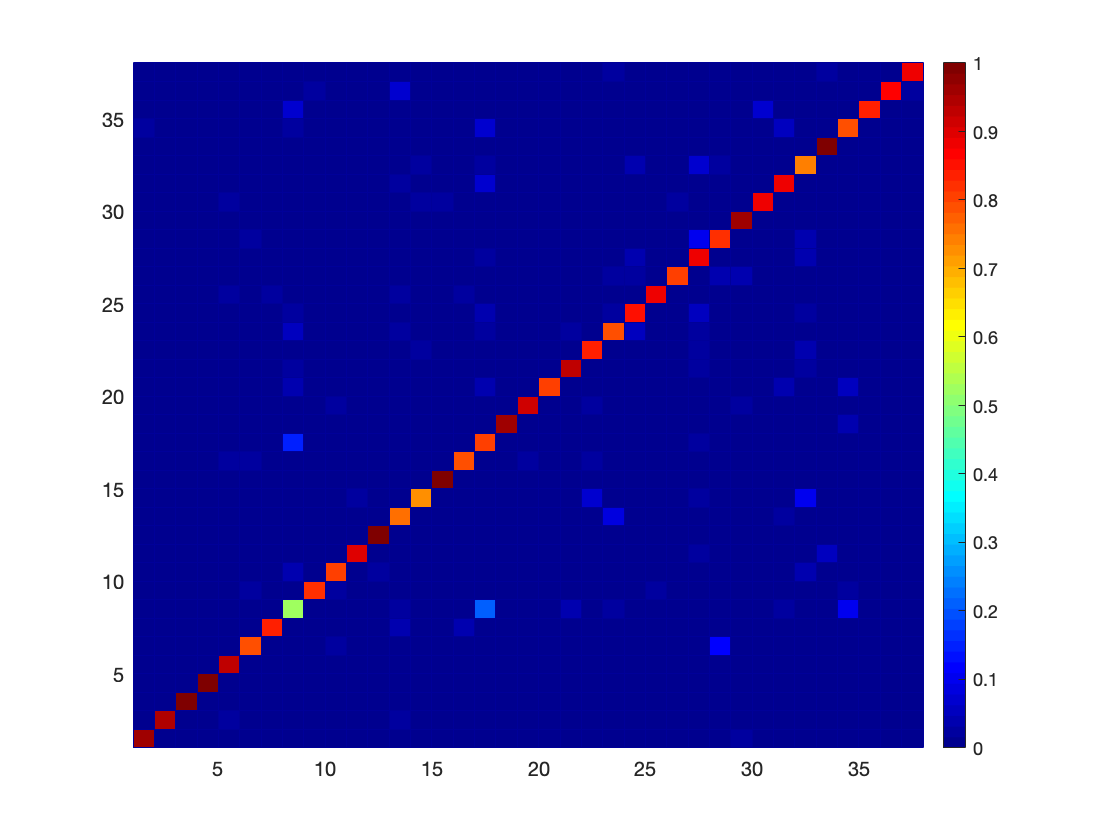

% plot confusion mat
plotConfusionMatrix(3, recognition(:,1),recognition(:,2));

## Consider EACH SESSION as a testing sample....

Use majority voting 

uniSessionTest = unique(sessionVecTest);
trueLabel = zeros(length(uniSessionTest),1);
predictLabel = zeros(length(uniSessionTest),1);
for i = 1 : length(uniSessionTest)
    curRecognition = recognition(sessionVecTest==uniSessionTest(i),:);
    trueLabel(i) = curRecognition(1,1);
    predictLabelVec = unique(curRecognition(:,2)); % to determine how many labels that are predicted
    predictLabelCount = zeros(length(predictLabelVec),1); % to count the predicted labels
    for ii=1: length(predictLabelVec)
        predictLabelCount(ii,:)=sum(curRecognition(:,2)==predictLabelVec(ii));
    end
    
    predictLabel(i)=min(predictLabelVec(predictLabelCount==max(predictLabelCount)));
end
noCorrect =0;
for i = 1 :length(predictLabel)
    if(predictLabel(i)==trueLabel(i))
        noCorrect = noCorrect +1;
    end
end
acc = noCorrect / length(predictLabel)

acc = 0.9656

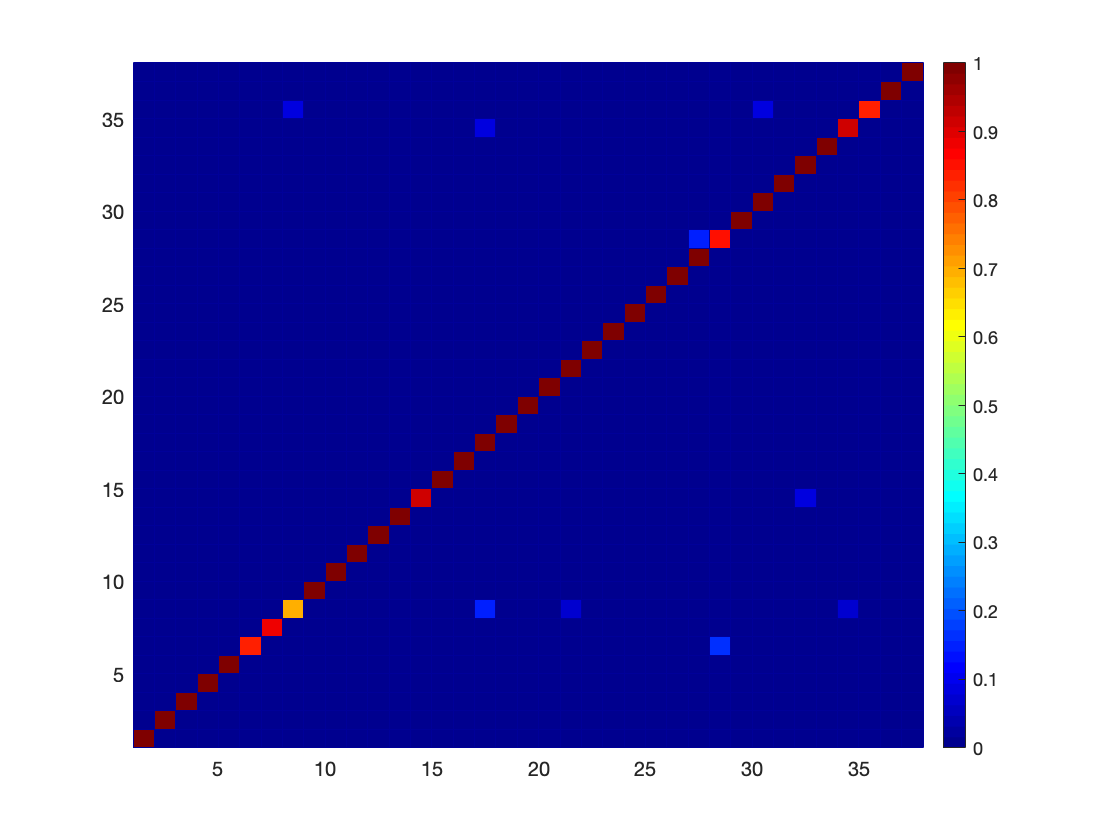

% plot confusion mat
plotConfusionMatrix(4, trueLabel,predictLabel);